## Import Data

clear all;
clc;
data = readtable("step_short_15V_75ohm.csv");
data = fillmissing(data,'nearest')

data = 1282×3 table
     Var1       Var2       Var3  
    _______    ______    ________

         -5         1           2
         -5         1           2
         -5    14.992    0.062892
    -4.9961    14.992    0.062892
    -4.9922    14.994     0.05033
    -4.9883    14.994     0.05033
    -4.9844    14.992     0.05033
    -4.9805    14.993     0.05033
    -4.9766    14.993     0.05033
    -4.9727    14.994     0.05033
    -4.9688    14.994     0.05033
    -4.9648    14.993     0.05033
    -4.9609    14.993     0.05033
     -4.957    14.994     0.05033
    -4.9531    14.994     0.05033
    -4.9492    14.993     0.05033


data([1,2],:) = []

data = 1280×3 table
     Var1       Var2       Var3  
    _______    ______    ________

         -5    14.992    0.062892
    -4.9961    14.992    0.062892
    -4.9922    14.994     0.05033
    -4.9883    14.994     0.05033
    -4.9844    14.992     0.05033
    -4.9805    14.993     0.05033
    -4.9766    14.993     0.05033
    -4.9727    14.994     0.05033
    -4.9688    14.994     0.05033
    -4.9648    14.993     0.05033
    -4.9609    14.993     0.05033
     -4.957    14.994     0.05033
    -4.9531    14.994     0.05033
    -4.9492    14.993     0.05033
    -4.9453    14.994     0.05033
    -4.9414    14.994     0.05033


data_test = readtable("step_multiple_60to70_75ohm.csv");
data_test = fillmissing(data_test,'nearest');
data_test([1,2],:) = [];
% Step info
step_bot=75;
step_top=80;

## Assign Variables

% Seperate values
t = table2array(data(:,1))+5

t =          0
    0.0039
    0.0078
    0.0117
    0.0156
    0.0195
    0.0234
    0.0273
    0.0312
    0.0352


ADC = round(table2array(data(:,2))/30*1024)

ADC =    512
   512
   512
   512
   512
   512
   512
   512
   512
   512


OCR = table2array(data(:,3))

OCR =     0.0629
    0.0629
    0.0503
    0.0503
    0.0503
    0.0503
    0.0503
    0.0503
    0.0503
    0.0503


% Match to duty cycle
OCR = round(OCR/5)*(step_top-step_bot)+step_bot;

% Find index before step
idx = find(OCR>75,1,'first')

idx = 57


% Trim data with new index
t = t(idx-5:end);
ADC = ADC(idx-5:end);
OCR = OCR(idx-5:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0039

## Plot Real Data

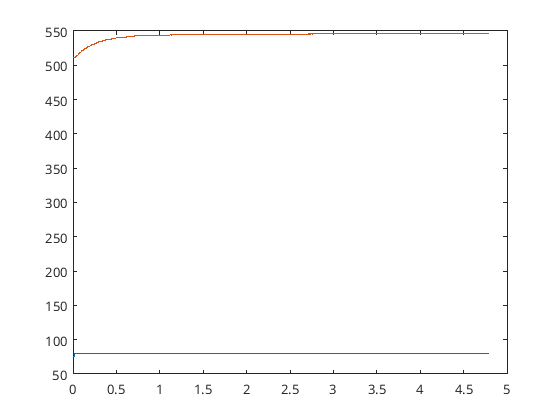

clf;
plot(t,OCR)
hold on
plot(t,ADC)
hold off

clf

## Identify Transfer Functions

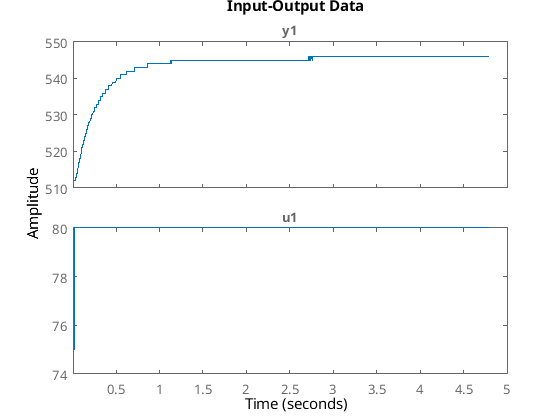

idd = iddata(ADC,OCR,T_s);
plot(idd)

G=tfest(idd,2,0)

G =
 
  From input "u1" to output "y1":
          1.121e05
  ------------------------
  s^2 + 802.3 s + 1.648e04
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using TFEST on time domain data "idd".
Fit to estimation data: 32.51%                  
FPE: 15.29, MSE: 15.16                          


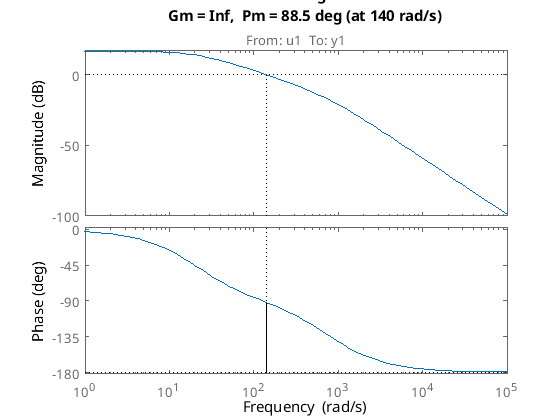

margin(G)

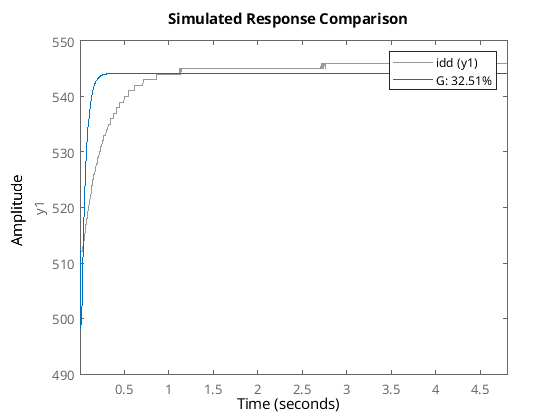

compare(idd,G)  % Passer meget godt med dataet

## Create PID Controller

abs(pole(G))

ans =   159.9133
    3.7954


gm = 70; Ni=2.5; alpha=1.5;
[wc, Kp, taui, taud, ok] = findpid(G, gm, Ni, alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc = 11.9851

Kp = 0.5562

taui = 0.2086

taud = 0.0681

ok = 1

s=tf('s');
Cpid=Kp*(taui*s+1)/(taui*s)*(taud*s+1)/(alpha*taud*s+1)

Cpid =
 
  0.007903 s^2 + 0.1539 s + 0.5562
  --------------------------------
       0.02132 s^2 + 0.2086 s
 
Continuous-time transfer function.



Cpid = minreal(Cpid)

Cpid =
 
  0.3708 s^2 + 7.22 s + 26.09
  ---------------------------
         s^2 + 9.786 s
 
Continuous-time transfer function.



Gol=minreal(G*Cpid)

Gol =
 
  From input to output "y1":
   1528 s^2 + 2.976e04 s + 1.076e05
  -----------------------------------
  s^4 + 173.5 s^3 + 2209 s^2 + 5939 s
 
Continuous-time transfer function.



Gcl=minreal(Gol/(1+Gol))

Gcl =
 
  From input "y1" to output "y1":
          1528 s^2 + 2.976e04 s + 1.076e05
  -------------------------------------------------
  s^4 + 173.5 s^3 + 3737 s^2 + 3.57e04 s + 1.076e05
 
Continuous-time transfer function.



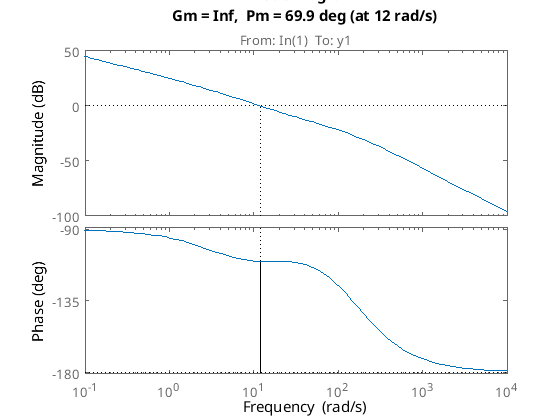

margin(Gol);

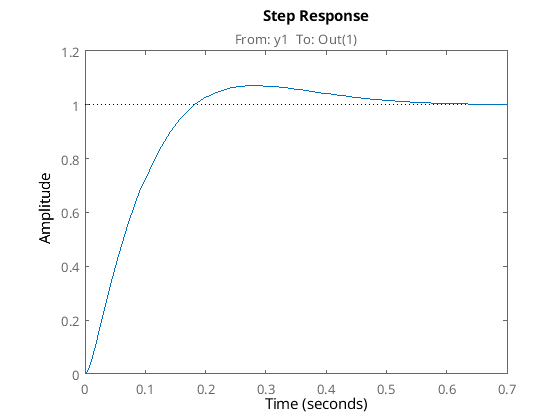

step(1*Gcl);

## Z-Transform

Gz=c2d(Cpid,1/10e3,'tustin');
Gz.Variable= 'z^-1'

Gz =
 
  0.371 - 0.7412 z^-1 + 0.3702 z^-2
  ---------------------------------
     1 - 1.999 z^-1 + 0.999 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




[num, den] = tfdata(Gz, 'v')

num =     0.3710   -0.7412    0.3702


den =     1.0000   -1.9990    0.9990


%open_system('pidTF2Code.slx')
%stepz([num],[den]);

e =[101,101,101];
u = [63,63,63];

u1=num(1)*e(1)+num(2)*e(2)+num(3)*e(3)-den(2)*u(2)-den(3)*u(3)

u1 = 63.0000

## Discrete Implementation

% Build time vector
dt=1/10e3;
t = 0:dt:14;

% Build step input
u = ones(size(t));
u(1:5)=0;

% Initialize values
y = zeros(size(t));

% Step through time and solve the difference equation
for i = 5:length(t)
        uvals = num(1)*u(i)+num(2)*u(i-1)+num(3)*u(i-2)+num(4)*u(i-3)+num(5)*u(i-4);
        yvals = -den(2)*y(i-1)-den(3)*y(i-2)-den(4)*y(i-3)-den(5)*y(i-4);
        y(i) = uvals + yvals;
end

Index exceeds the number of array elements. Index must not exceed 3.


scatter(t,y,3)